# Gabriel Colangelo

clear
close all
clc

## Problem 1a - i)

Find: type, $$a,e,r_D,v_D,\gamma_D, \theta^*_D, r_A, v_A, \gamma_A, |\Delta \bar{v}_D|, \alpha_D, |\Delta \bar{v}_A|, \alpha_A$

Assume: TA = 260, TOF = 8 hours, initial circular orbit radius of 2 Earth radii and a final circular orbit radii of 6.6 Earth Radii. Coplanar Orbit

% Earth Parameters
mu_earth    = 398600.4415;
R_earth     = 6378.1363;

% Orbit radii
r1_A        = 2*R_earth;
r2_A        = 6.6*R_earth;

% Transfer angle
TA_A        = 260;

% Time of flight
TOF_A       = 8*3600;

% Call function to solve Lamberts Problem
probA       = LambertsProblem(TOF_A, r1_A, r2_A, TA_A, mu_earth);
fprintf('The semi major axis of the transfer orbit is %.4E km',probA.a)

The semi major axis of the transfer orbit is 2.6822E+04 km


$$\phi = 360 - TA = 100 \ [deg]\\
\text{Law of cosines from space triangle: } \ c^2 = r_1^2 + r_2^2 - 2r_1r_2\cos{\phi} \\
\text{Semi-perimeter: } \ s = (r_1 + r_2 + c)/2\\
\text{Minimum energy semi major axis} \ a_{min} =  s/2 = 2.5227 \times 10^4 \ [km] \\
\beta_{min} = 2\sin^{-1}{\sqrt{\frac{s-c}{2a_{min}}} = 34.3 \ [deg]\\
TOF_{min} = \sqrt{\frac{a^3}{\mu}}[(\pi - \beta_{min} ) - (\sin{\pi} - \sin{\beta_{min}})] = 5.47 \ [hour]
$$


**The transfer angle is greater than 180 degrees, therefore the transfer type is a 2. The minimum time of flight **

**is less than the desired time of flight, therefore the transfer type is a B. The transfer type is ****2B.**

For a type 2B, the true $\alpha$ and $\beta$ values are related to their principal values through:


$$\alpha = 2\pi - \alpha_0\\
\beta = -\beta_0$$


Lamberts problem is solved numerically for $a$ using a bisection method:


$$\beta_0= 2\sin^{-1}{\sqrt{\frac{s-c}{2a}} \\
\alpha_0= 2\sin^{-1}{\sqrt{\frac{s}{2a}} \\
TOF = \sqrt{\frac{a^3}{\mu}}[(\alpha - \beta ) - (\sin{\alpha} - \sin{\beta})] = 8\ [hour] \\
\\
\underline{\mathbf{a = 2.6822 \times 10^4 \ [km]}}$$


% Calculate semi latus rectum
p_A     = max((4*probA.a*(probA.s - r1_A)*(probA.s - r2_A)/probA.c^2)*...
          [sin((probA.alpha + probA.beta)/2)^2, sin((probA.alpha - probA.beta)/2)^2]);

% Calculate eccentricity
e_A     = sqrt(1 - p_A/probA.a);
fprintf('The transfer eccentricity is %.4f ',e_A)

The transfer eccentricity is 0.6379 


$$\alpha  = 208.26 \ [deg] \\
\beta = -33.27 \ [deg] \\
p = a(1 - e^2) = \frac{4a(s-r_1)(s-r_2)}{c^2}\sin^2{(\frac{\alpha \pm \beta}{2})} = 15906.8 \ \text{or} \ 11771.2 \ [km]\\
\bar{OF} = 2ae$$


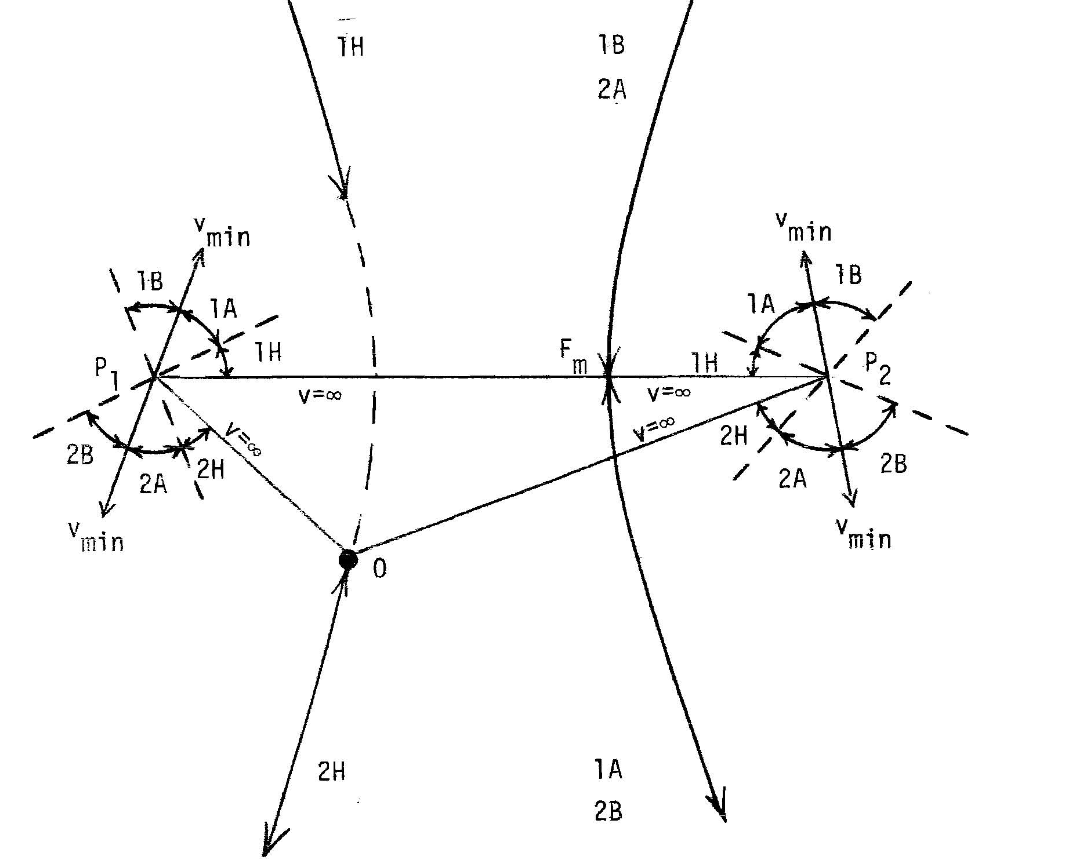

For 2B transfer type, a smaller e is needed as observed in the solution space diagram above. A smaller e will cause an increase in semi-latus rectum. Therefore, the necessary semi-latus rectum value is the larger option (15906.8 [km]).


$$e = \sqrt{1 - \frac{p}{a}} \\
\\
\mathbf{e = 0.6379}$$
